#  Statistical Modeling Textbook: Linear Regression Model 

##  Statistical Modeling for Data Analysis #1 Theory (1) 

clear;
close all;

###  1. Confidence Intervalsand Prediction Intervals 

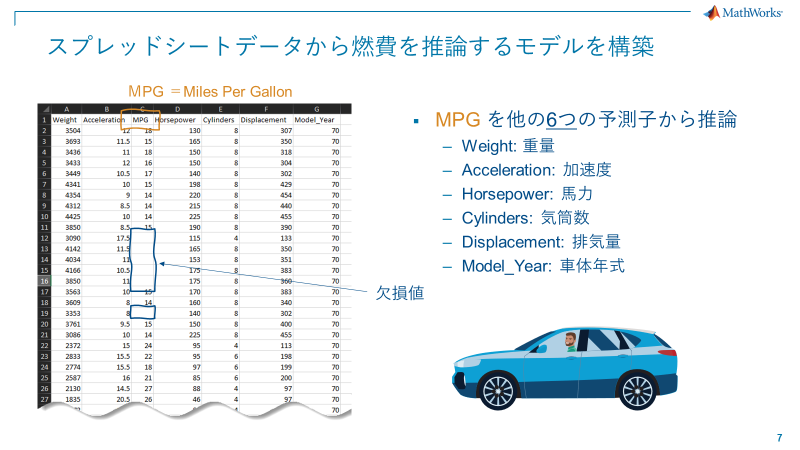

A: 

I want to improve fuel efficiency.I think weight has an effect after all..." 

"The first step to quantifying is, of course, linear regression. First, import the data." 

GUIdataImport = false;
if GUIdataImport
    uiimport("tblraw.xlsx");
else
    load tblraw.mat
end 

** Practice **

- Importing and exporting csv files using the file import app 

- MATLAB code generation from the file import app 

** Pre-processing **

B: 

"There are gaps in the data, so it's best to clean them up." "Data science" etiquette. MATLAB has many functions for preprocessing." 

(see [Data preprocessing](https://jp.mathworks.com/help/matlab/preprocessing-data.html)) 

A: 

"I think it's convenient, but preprocessing requires trial and error. That's right.To be honest, it's a pain to execute functions one after another, and it's bad for productivity, so I don't want to do it.'' 

``By the way, Mr. B, who are you?'' 

B: 

``Data analysts are There are many people who do things that are unproductive, but Mr. A has changed his mind. Leaving aside who I am, I'd like to introduce a useful tool." 

"Pre-processing is performed with a semi-GUI. Live Task is a dream tool that can be used!'' 

A: 

``Hmmm'' 

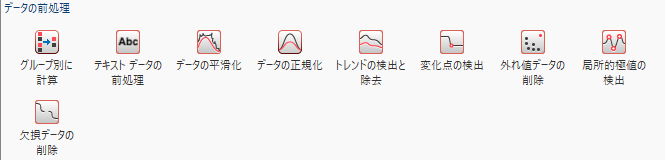

Live Task 

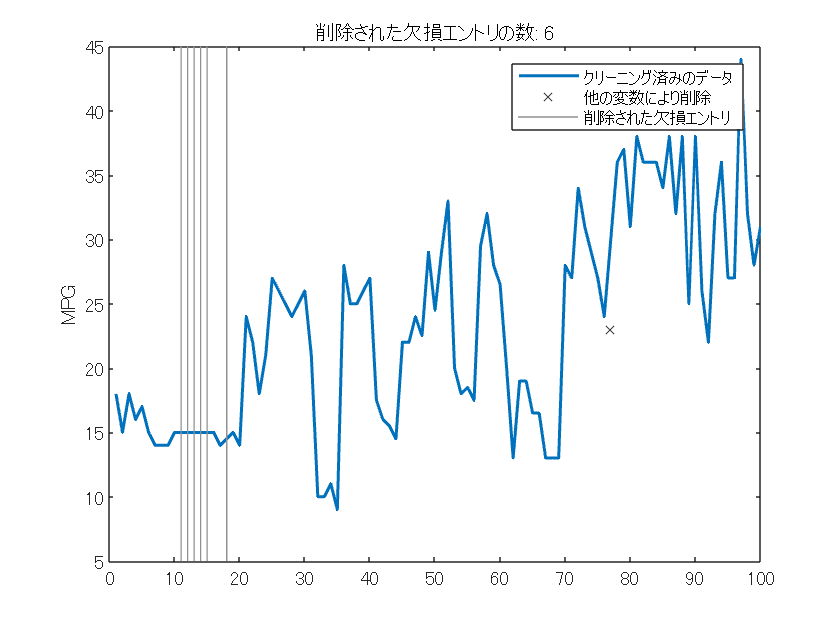

% Delete missing data
[tbl,missingIndices] = rmmissing(tblraw);

% Viewing results
clf
plot(find(~missingIndices),tbl.MPG,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","クリーニング済みのデータ")
hold on

indicesForPlot = ismissing(tblraw.MPG);

% Plot data for rows with missing entries in other variables
mask = missingIndices & ~indicesForPlot;
plot(find(mask),tblraw.MPG(mask),"x","Color",[64 64 64]/255,...
    "DisplayName","他の変数により削除")

% Plot of deleted missing entries
x = repelem(find(indicesForPlot),3);
y = repmat([ylim(gca) missing]',nnz(indicesForPlot),1);
plot(x,y,"Color",[145 145 145]/255,"DisplayName","削除された欠損エントリ")
title("削除された欠損エントリの数: " + nnz(indicesForPlot))

hold off
legend
ylabel("MPG")

clear indicesForPlot mask x y
clearvars -except tbl tblraw

** Plot MPG vs Weight **

A: 

``Now that the data is clean, let's plot it.'' 

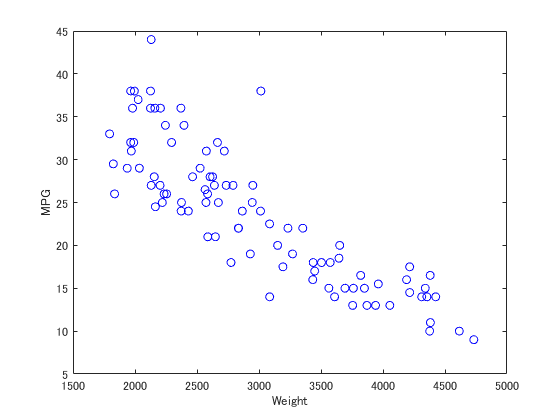

plot(tbl.Weight, tbl.MPG,'bo');
xlabel("Weight");
ylabel("MPG");
set(gcf, 'visible', 'on'); 

"It's easy to draw a line here using the basic functions of Figure!" 

"Now that we've found the coefficients, 90% of the work is complete! Data analysis is a piece of cake." 

Tools  >> Basic approximation 

allows you to create a simple approximation model. 

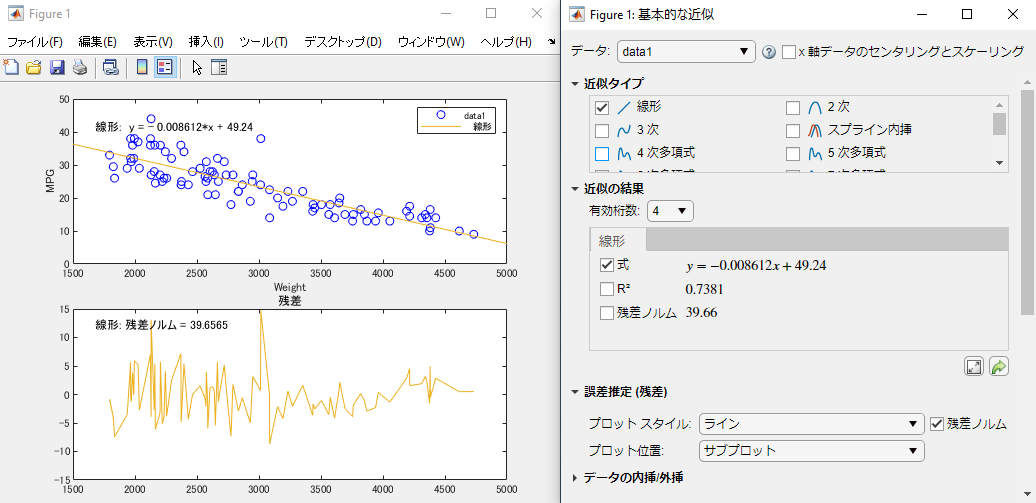

B: 

"This much can be done in Excel, so why not do something a little more 'analytical'?" 

"Assuming the following model, create a linear regression model. 


$$y = \beta_0 + \beta_1 x + \epsilon \\
\text{where $y\;$ is MPG and $x\;$ is Weight.}\\
\text{and where, } \epsilon \sim N(0, \sigma^2). $$


A: 

"Gunnu. Linear regression....I use it a lot, but I don't really understand it very well. I'd like you to organize my knowledge..." 

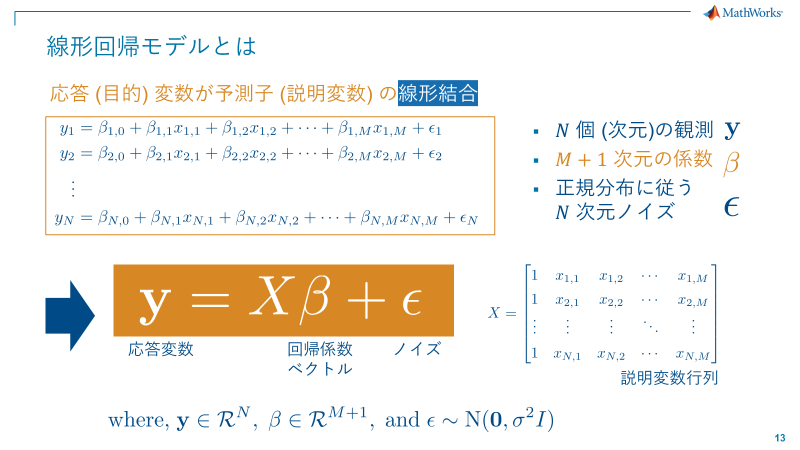

A: 

"It's like this. ?" 

B: 

"That's a good summary. When there is one predictor, it is called "simple regression," and when there are multiple predictors, it is called "multiple regression." 

"In this case, Observation noise is treated as a random variable that follows a normal distribution with mean 0. It can be expressed as follows." 


$$\epsilon \sim \mathbf{N}(0,\sigma^2)$$


####  Supplementary explanation: Maximum likelihood estimation method 

open("LogLikelihood.mlx"); 

A: 

"Linear regression uses fitlm. Just do this!'' 

linear_mdl = fitlm(tbl,"MPG~1+Weight");
disp(linear_mdl); 

線形回帰モデル: 
    MPG ~ 1 + Weight

推定された係数: 
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        49.238        1.6504     29.834    9.0258e-49
    Weight         -0.0086118    0.00053775    -16.014    3.2405e-28


観測数: 93、誤差の自由度: 91
平方根平均二乗誤差: 4.16
決定係数: 0.738、自由度調整済み決定係数: 0.735
F 統計量 - 定数モデルとの比較: 256、p 値は 3.24e-28 です


B: 

``Mr. A, do you know how to express MPG~1+Weight?'' 

A: 

``This is Wilkinson's notation. There is also a way to specify a model, but this time I used this.'' 

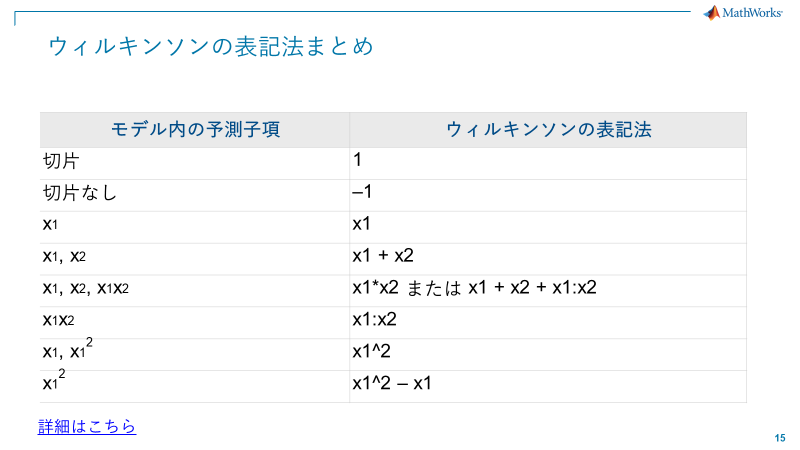

A: 

``Various analysis results have come out, but since all I have to do is draw a line, I just plot the objects that come out. And…” 

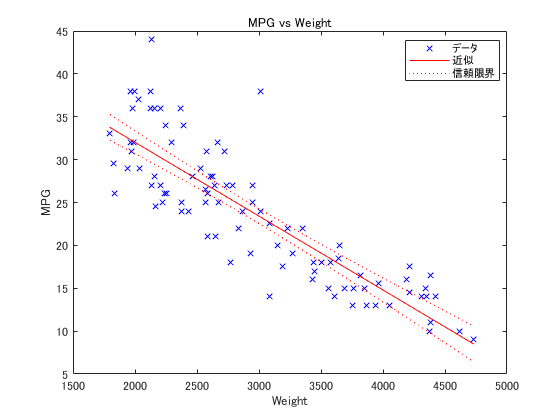

plot(linear_mdl);

linear_mdl.Coefficients 

ans = 2×4 table
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        49.238        1.6504     29.834    9.0258e-49
    Weight         -0.0086118    0.00053775    -16.014    3.2405e-28


“Okay, I got the coefficient, so it’s okay.” 

“The coefficient of determination is also 0.74, so the correlation is perfect! Perfect!” 

A: 

“According to this diagram, weight If is 3000, the predicted value is about 23.'' 

B: 

``Let's do it accurately. Use feval:'' 

y_pred_1500 = feval(linear_mdl,3000) 

y_pred_1500 = 23.4029

A: 

``Okay, now you can give a presentation!'' 

B: 

"Eh..." 

..... On the day of the presentation..... 

C: 

"Mr. A, I understand the content. But what is the red line in that diagram? ?'' 

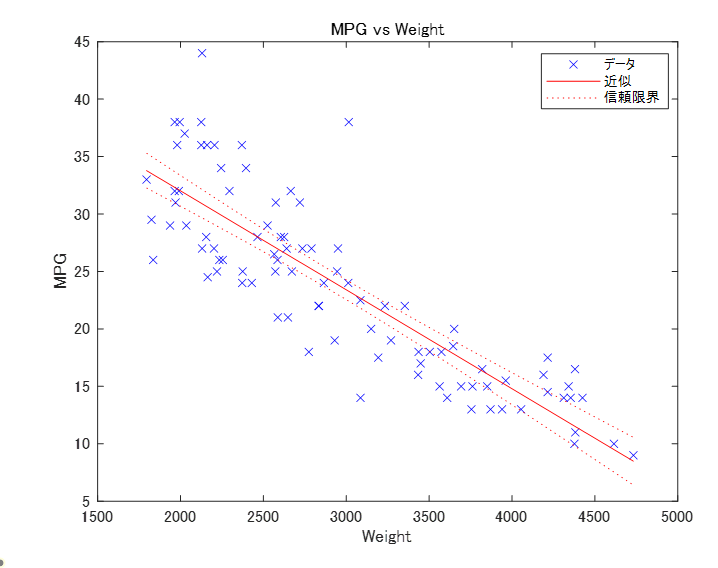

A: 

``This is called a confidence interval, and it represents a prediction with a probability of 95% (smug)'' 

C: 

``95%!? But the data doesn't stick out at all. No matter how I look at it, it doesn't look like 95%. Please tell me what you mean.'' 

A: 

"Indeed...gunnu..." 

#### ** Discussion 1: What does it mean? **

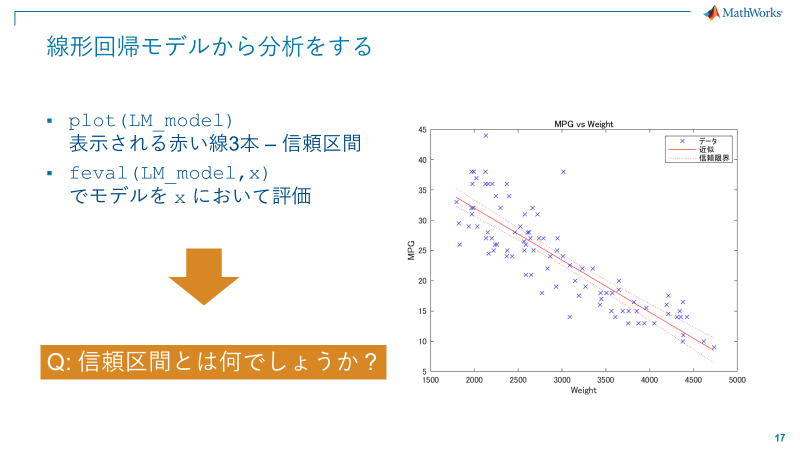

####  Problem 1.1: What is Mr. A's problem? 

Answer: This represents the "confidence interval of the regression curve." In other words, 

"If you collect data in the same way and analyze it in the same way, 95 out of 100 times it will fit within that frame." 

This is different from the prediction interval, which represents the prediction range of the data to be acquired next. 

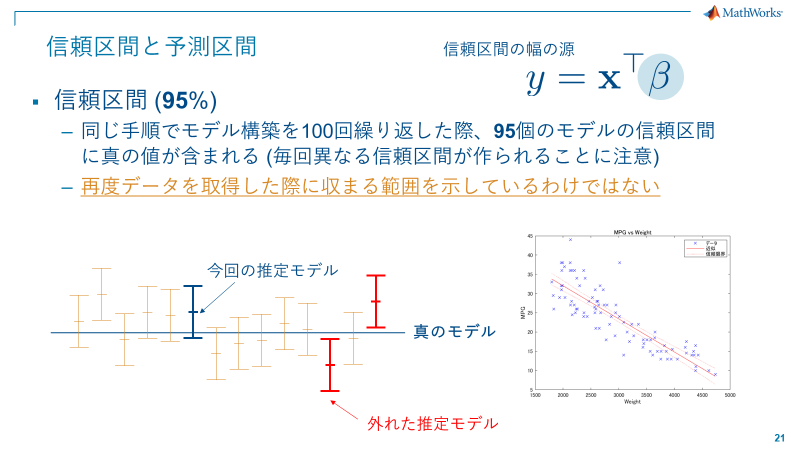

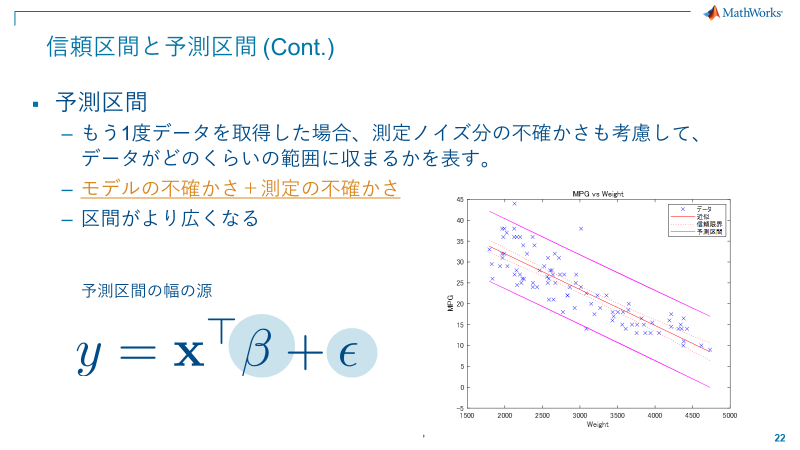

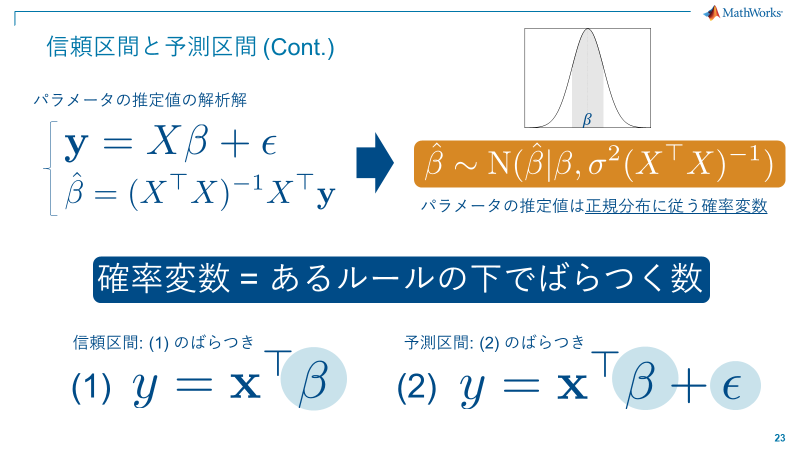

When written as a formula, the confidence interval is 


$$\hat{\mathbf{y}} = X\hat{\mathbf{\beta}}$$


and the prediction interval is larger by 


$$y_{pred} = \hat{y} + \epsilon$$


. It's no good if you don't take this into account. 

####  Demonstration: Comparison of confidence intervaland prediction interval 

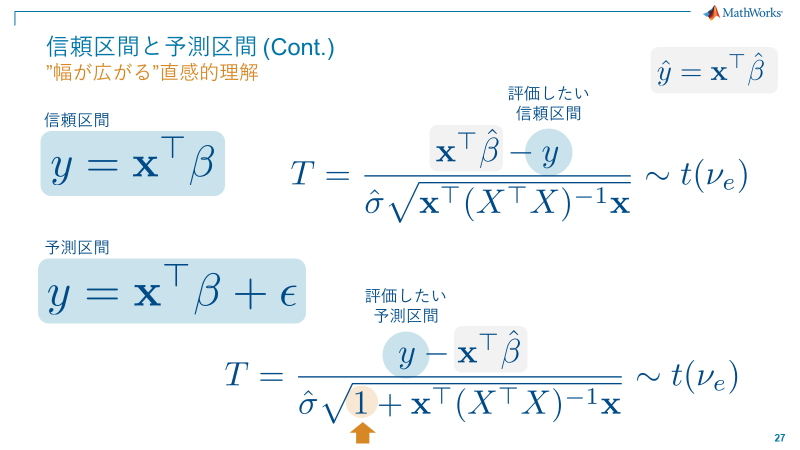

Reference: [Confidence and Prediction Bounds](https://www.mathworks.com/help/curvefit/confidence-and-prediction-bounds.html)

Reference: [predict](https://www.mathworks.com/help/stats/linearmodel.predict.html#namevaluepairarguments)

% Sorting data
tbl_new = sortrows(tbl,"Weight","ascend");

% model confidence interval
[~, y_confInt] = predict(linear_mdl, tbl_new,'Prediction','curve');

% Calculating prediction intervals
[y_mean, y_predInt] = predict(linear_mdl, tbl_new,'Prediction','observation'); 

Visualization above & Overlapping plot 

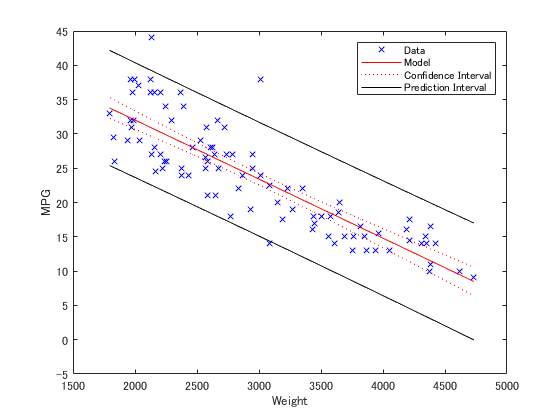

plot(tbl_new.Weight,tbl_new.MPG,'xb', tbl_new.Weight, y_mean,'r-'); % Plot the mean line
hold on;
plot(tbl_new.Weight, y_confInt(:,1),'r:', tbl_new.Weight, y_confInt(:,2),'r:'); % Confidence interval plot
plot(tbl_new.Weight, y_predInt(:,1),'k' , tbl_new.Weight, y_predInt(:,2),'k');  % Prediction interval plot
xlabel("Weight");
ylabel("MPG");
legend('Data', 'Model', 'Confidence Interval',"",'Prediction Interval',"");
hold off; 

** Supplementary explanation 1 **

' `Prediction`' Options include' `curve`' and' `observation`' can be selected. The predictive model is: 


$$y = f(X) + \epsilon
$$


and $f
$ is the fitted regression model. Returns the confidence interval for 

- ' `curve`' - $f(X_{new})$. Returns the confidence interval for 

- ' `observatoin`' - $y$. This is large due to the noise variance during observation. 

** Supplementary explanation 2 **

The confidence interval of the parameter can be obtained with `coefCI(mdl,alpha)`. `alpha` allows you to obtain any confidence interval. If 

95%, set `alpha` = 0.05. 

#### ** Summary of features of linear modelsand linear regression models **

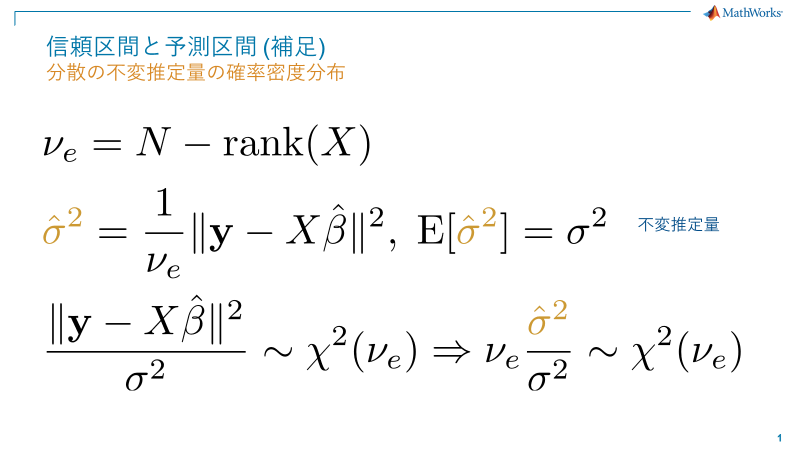

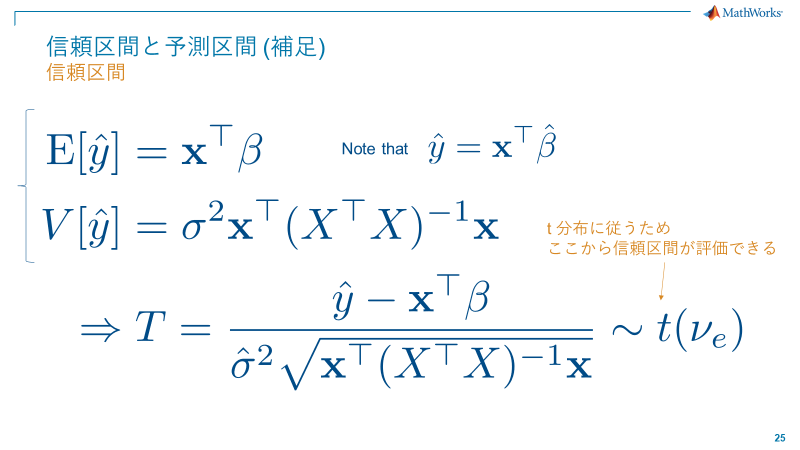

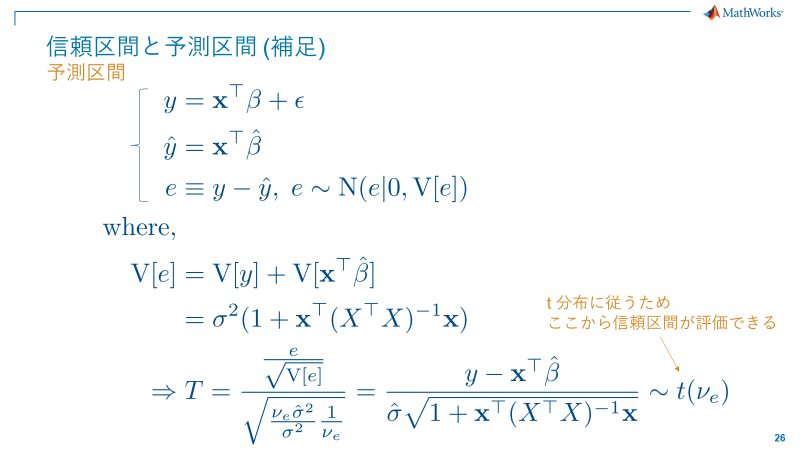

##  Summary of points 1 

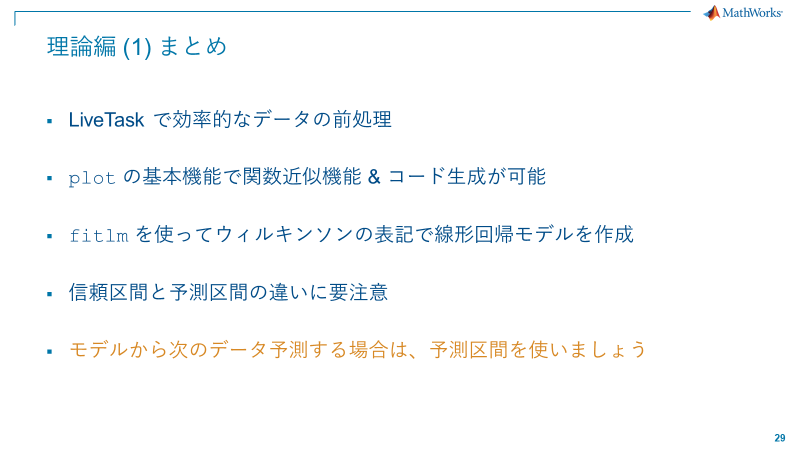

* Copyright 2022 - 2023 The MathWorks, Inc *